# Bespoke Noise Generator

This script applies a scaled noise correction to meet a user defined SNR. It:

- calculates the signal power for each element of the baseline data (complex array input).

- determines the required noise power to achieve the desired SNR.

- generates the complex noise matrix for each element.

- adds the noise matrix to the original matrix to create the noisy matrix.

- the noisy matrix is then processed by the slice_SNR function.

- the baseline SNR vs noisy matrix SNR is visualised; as well as the SNR, Signal and Noise for each the Baseline and the Noisy data across subplots.

required_SNR_dB = 15; % Desired SNR in dB [dB].
required_SNR_linear = 10^(required_SNR_dB / 10); % [linear]

baseline_matrix_complex = active_inputdata; % [complex]
baseline_matrix_linear = active_slices_range_doppler_abs; % [linear]

% Calculate signal power for each element
signalPower_linear = zeros(1, length(baseline_matrix_linear)); % [linear]
for i = 1:length(baseline_matrix_linear)
    signalPower_linear(i) = (max(baseline_matrix_linear{i}(:))).^2; % [linear]
end

% Calculate noise power for each element
noisePower_linear = signalPower_linear / required_SNR_linear; % [linear]

% Generate a noise matrix for each element
noise_complex = cell(1, length(baseline_matrix_complex));
for i = 1:length(baseline_matrix_complex)
    % Use sqrt(noisePower_linear(i)/2) for complex noise
    noise_complex{i} = sqrt(noisePower_linear(i)/2) * ...
        (randn(size(baseline_matrix_complex{i})) + 1i .* randn(size(baseline_matrix_complex{i}))); % [complex]
end

% Add the original matrix to the new noise matrix
noisyMatrix_complex = cell(1, length(baseline_matrix_complex));
for i = 1:length(baseline_matrix_complex)
    noisyMatrix_complex{i} = baseline_matrix_complex{i} + noise_complex{i};
end

% Calculate linear and dB values for each element in noise_complex
noise_linear = cell(1, length(noise_complex));
noise_dB = cell(1, length(noise_complex));
for i = 1:length(noise_complex)
    noise_linear{i} = abs(noise_complex{i});  % Linear values
    noise_dB{i} = 20*log10(abs(noise_complex{i}));  % dB values
end

% Add the original matrix to the new noise matrix to generate the noisy matrix
noisyMatrix_complex = cell(1, length(baseline_matrix_complex));
for i = 1:length(baseline_matrix_complex)
    noisyMatrix_complex{i} = baseline_matrix_complex{i} + noise_complex{i}; % [complex]
end  

### Use slice_SNR to process the noisyMatrix

% User defined ROI indices
active_roi_indices_rows = 320:420; % input to slice_SNR func to calculate noise of roi
active_roi_indices_cols = 65:99;   % input to slice_SNR func to calculate noise of roi
noisy_active_signal=zeros(1,length(noisyMatrix_complex)); % [dB] once func populates
noisy_active_noise=zeros(1,length(noisyMatrix_complex)); % [dB] once func populates
noisy_active_noise_abs=zeros(1,length(noisyMatrix_complex)); % absolute mean noise (not dB) once func populates
noisy_active_SNR=zeros(1,length(noisyMatrix_complex)); % [dB] once func populates
noisy_active_slices_range_doppler = createArrays(length(noisyMatrix_complex), size(noisyMatrix_complex{1,1})); % [dB] once func populates
noisy_active_slices_range_doppler_abs = createArrays(length(noisyMatrix_complex), size(noisyMatrix_complex{1,1})); % absolute not dB, once func populates
noisy_active_signal_idx = zeros(1,length(noisyMatrix_complex));

for i=1:length(noisyMatrix_complex)
    [noisy_active_signal(i),...
        noisy_active_noise(i),...
        noisy_active_SNR(i),...
        noisy_active_slices_range_doppler{i},...
        noisy_active_signal_idx(i),...
        noisy_active_noise_abs(i),...
        noisy_active_slices_range_doppler_abs{i}]=slice_SNR(noisyMatrix_complex{1,i}, active_roi_indices_rows, active_roi_indices_cols);
end   

Calculating Mean Values for Plot

mean_active_SNR_dB = mean(active_SNR) % mean mean of the baseline SNR [db]

mean_active_SNR_dB = 62.2783

mean_noisy_active_SNR_dB = mean(noisy_active_SNR) % mean of the noise SNR [dB]

mean_noisy_active_SNR_dB = 16.2793

mean_delta = -(mean_active_SNR_dB - mean_noisy_active_SNR_dB) % - to show reduction [dB]

mean_delta = -45.9991

### Visualising the Baseline Matrix & the Noisy Matrix

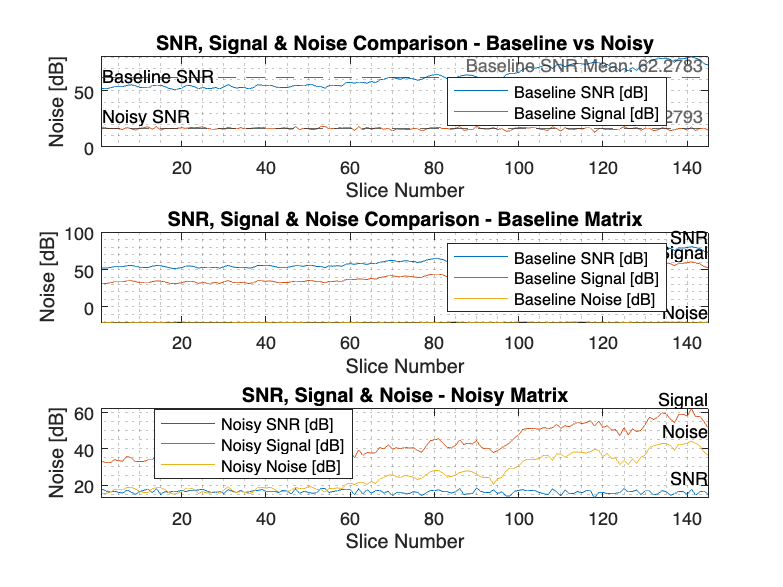

figure
subplot(3,1,1)
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR)

grid minor
title('SNR, Signal & Noise Comparison - Baseline vs Noisy');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])
% Add text annotations
text(1, (active_SNR(1:1))*1.05, 'Baseline SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left');
text(1, (noisy_active_SNR(1:1))*1.05, 'Noisy SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'left');
yline(mean_active_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(mean_active_SNR_dB)], ...
    'LineWidth', 0.25);
%    'FontSize', 6);
yline(mean_noisy_active_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(mean_noisy_active_SNR_dB)], ...
    'LineWidth', 0.25);
%    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Baseline Signal [dB]',  ...
    'location', 'best')

subplot(3,1,2)
plot(1:length(active_SNR), active_SNR, ...
    1:length(active_signal), active_signal, ...
    1:length(active_noise), active_noise)
legend( 'Baseline SNR [dB]', ...
    'Baseline Signal [dB]', ...
    'Baseline Noise [dB]',...
    'location', 'best')
grid minor
title('SNR, Signal & Noise Comparison - Baseline Matrix');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])
% Add text annotations
text(length(active_SNR), max(active_SNR), 'SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(length(active_signal), max(active_signal), 'Signal', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(length(active_noise), max(active_noise), 'Noise', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');

subplot(3,1,3)
plot(1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_signal), noisy_active_signal, ...
    1:length(noisy_active_noise), noisy_active_noise)
legend( 'Noisy SNR [dB]', ...
    'Noisy Signal [dB]', ...
    'Noisy Noise [dB]',...
    'location', 'best')
grid minor
title('SNR, Signal & Noise - Noisy Matrix');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(active_SNR)])
% Add text annotations
text(145, max(noisy_active_SNR), 'SNR', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(145, max(noisy_active_signal), 'Signal', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');
text(145, max(noisy_active_noise), 'Noise', ...
    'VerticalAlignment', 'bottom', ...
    'HorizontalAlignment', 'right');

#### Observation:

The differences in the profiles of 'active_SNR' and the 'noisy_active_SNR' can be attributed to the nature of the signal and noise addition.

Baseline SNR ('active_SNR'):  this represents the Signal-to-Noise Ratio (SNR) of the original data. The profile shows the quality of the signal across different slices.

Noisy Signal SNR ('noisy_active_SNR'):  this represents the SNR after adding artificial noise to the original data. The artificial noise affects the SNR, and you are seeing a different profile due to the added noise. The flatter profile may indicate that the added noise is affecting different slices uniformly.

### Calculating Metrics for Comparison - Min, Mean & Max

min

%%% Do this wihtin threshold script


mean

%%% Do this wihtin threshold script

max

%%% Do this wihtin threshold script



#### Plot Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

Moving the Noisy SNR signal to have a mean = 0dB

noisy_active_SNR_dB_zeroed = noisy_active_SNR - mean_noisy_active_SNR_dB; % [dB]

Plot the Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean

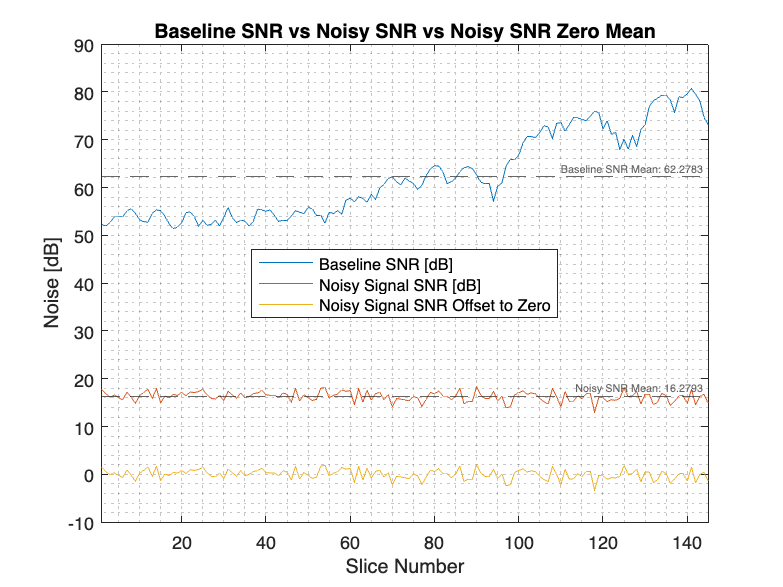

figure
plot(1:length(active_SNR), active_SNR, ...
    1:length(noisy_active_SNR), noisy_active_SNR, ...
    1:length(noisy_active_SNR_dB_zeroed), noisy_active_SNR_dB_zeroed)
yline(mean_active_SNR_dB, '--', ...
    ['Baseline SNR Mean: ' num2str(mean_active_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
yline(mean_noisy_active_SNR_dB, '--', ...
    ['Noisy SNR Mean: ' num2str(mean_noisy_active_SNR_dB)], ...
    'LineWidth', 0.25, ...
    'FontSize', 6);
legend( 'Baseline SNR [dB]', ...
    'Noisy Signal SNR [dB]', ...
    'Noisy Signal SNR Offset to Zero', '', '', ...
    'location', 'best')
grid minor
title('Baseline SNR vs Noisy SNR vs Noisy SNR Zero Mean');
ylabel('Noise [dB]');
xlabel('Slice Number');
xlim([1, length(noisy_active_SNR)])